**Linear Regression with one Variable Model**

clear all
close all
data = load('USA_PoP_GDP.csv'); % read comma separated data
X = data(:, 1); y = data(:, 2);

A function to display plot

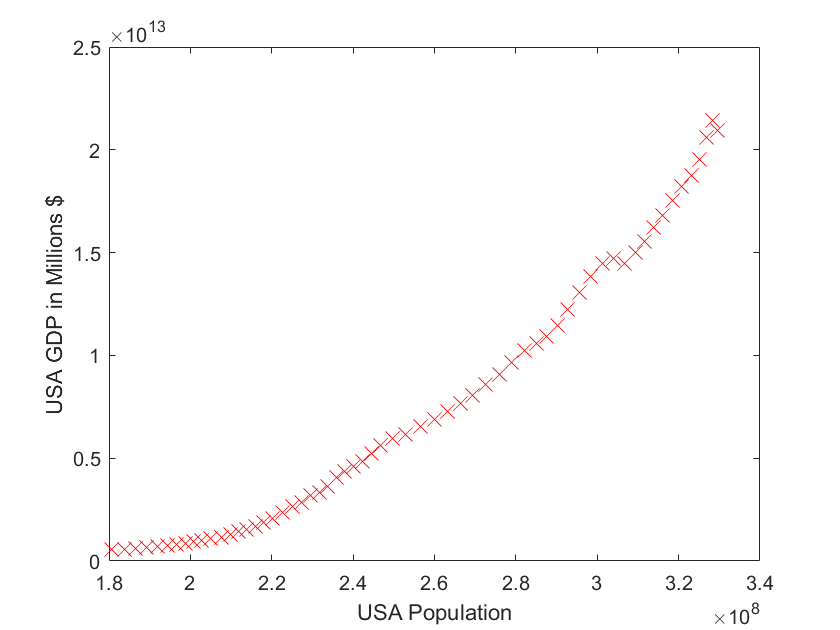

plot(X,y, 'rx', 'MarkerSize', 10)
ylabel('USA GDP in Millions $'); % Set the y-axis label
xlabel('USA Population'); % Set the x-axis label

Initializing the Linear regression model 

m = length(X); % number of training examples
[X, mu, sigma] = featureNormalize(X); % Normalizing X
[y, mu, sigma] = featureNormalize(y); % Normalizing y
X = [ones(m,1),X(:,1)]; % Add a column of ones to x
theta = zeros(2, 1); % initialize fitting parameters
iterations = 100; % Choose number of iterations
alpha = 0.03; %Chose the learning rate Alpha
%alpha = 0.01;
%iterations = 125;

Computing the cost function $J(\theta)$

% Compute and display initial cost with theta all zeros
computeCost(X, y, theta)

ans = 0.4918

Gradient descent

% Run gradient descent:
% Compute theta
[theta, J_history] = gradientDescent(X, y, theta, alpha, iterations);
% Print theta to screen
% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

Theta computed from gradient descent:
0.000000,
0.927388

Plot the linear fit

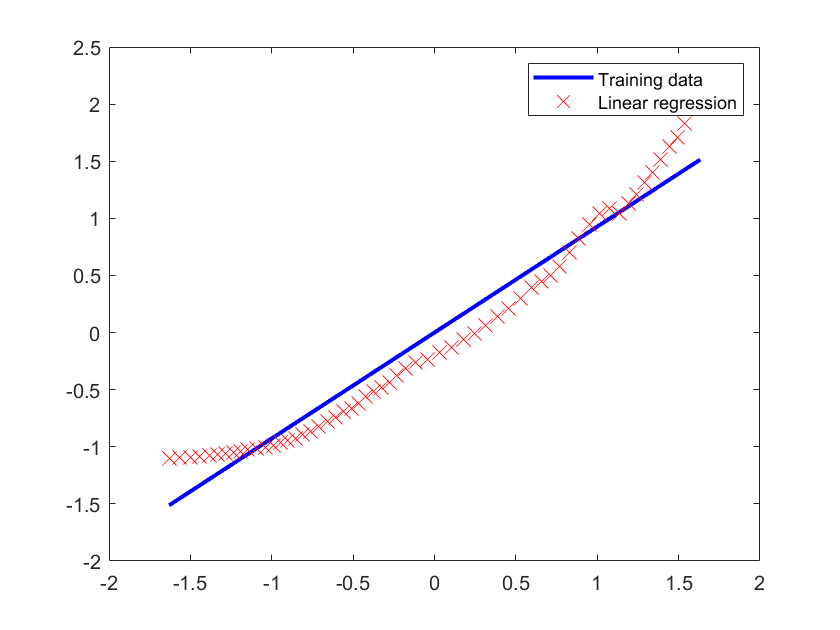

% Plot the linear fit
%hold on; % keep previous plot visible
plot(X(:,2), X*theta, 'b-' , 'LineWidth' ,2)
hold on 
plot(X(:,2),y, 'rx', 'MarkerSize', 10)
hold off % don't overlay any more plots on this figure
legend('Training data', 'Linear regression')

Check for convergence

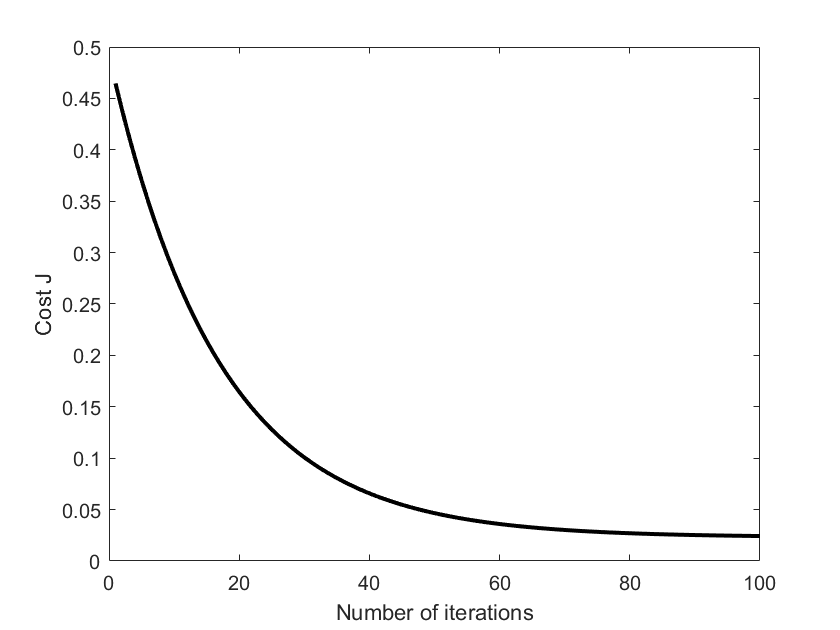

% Plot the convergence graph
plot(1:iterations, J_history, '-k', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');

Make predictions

% Predict values for population sizes of 35,000 and 70,000
%predict1 = [1, 20] *theta;
%fprintf('For population = 20,000, we predict a profit of %f\n', predict1*10000);
%predict2 = [1, 25] * theta;
%fprintf('For population = 25,000, we predict a profit of %f\n', predict2*10000);